clc; clear; close all;

%% ── Parámetros ──────────────────────────────────────────────────────────
T               = 24;
N               = 3;            % horizonte MPC
num_escenarios  = 100;

SOC_max = 15; SOC_min = 4;
eta_c   = 0.95; eta_d = 0.95;
c_batt  = 0.01;

%% ── Arrays de resultados ────────────────────────────────────────────────
Costes               = zeros(num_escenarios,1);
Costes_sin_batt      = zeros(num_escenarios,1);
Eficiencias          = zeros(num_escenarios,1);
Grid_total           = zeros(num_escenarios,1);
Coverage             = zeros(num_escenarios,1);
Horas_llena          = zeros(num_escenarios,1);
Horas_vacia          = zeros(num_escenarios,1);
Porcentaje_renovable = zeros(num_escenarios,1);

% Para las gráficas de proporción energética
Energia_red_total        = zeros(num_escenarios,1);
Energia_renovable_total  = zeros(num_escenarios,1);

P_grid_hist_matrix      = zeros(num_escenarios,T);
P_charge_hist_matrix    = zeros(num_escenarios,T);
P_discharge_hist_matrix = zeros(num_escenarios,T);
SOC_hist_matrix         = zeros(num_escenarios,T);

%% ── Bucle de escenarios ─────────────────────────────────────────────────
for s = 1:num_escenarios
    t_vec = 1:T;

    % Demanda
    P_load = (4 + 3*sin((t_vec-7)*pi/12)) .* (0.8 + 0.4*rand(1,T));
    P_load = max(P_load, 0);

    % Solar (pico mediodía)
    P_solar = 5 * max(0, sin((t_vec-6)*pi/12)) .* (0.8 + 0.4*rand(1,T));

    % Eólica (más viento de noche)
    P_aeolica = (2 + 1*sin((t_vec+5)*pi/12)) .* (0.7 + 0.6*rand(1,T));
    P_aeolica = max(P_aeolica, 0);

    % Precio con diferencial valle/punta marcado
    base_price = [0.08*ones(1,8), 0.35*ones(1,8), 0.15*ones(1,8)];
    price      = base_price .* (0.9 + 0.2*rand(1,T));

    % ── Simulación CON batería (MPC) ─────────────────────────────────────
    SOC              = 10;
    P_grid_hist      = zeros(1,T);
    P_charge_hist    = zeros(1,T);
    P_discharge_hist = zeros(1,T);
    SOC_hist         = zeros(1,T);

    for t = 1:T
        idx   = t:min(t+N-1, T);
        H_eff = length(idx);
        n     = 4*H_eff;

        % Función de coste: minimizar gasto red + desgaste batería
        f = [price(idx), c_batt*ones(1,H_eff), c_batt*ones(1,H_eff), zeros(1,H_eff)];

        % Balance de potencia: P_grid - P_charge + P_discharge = P_load - P_ren
        Aeq  = zeros(H_eff, n);
        beq  = (P_load(idx) - P_solar(idx) - P_aeolica(idx))';
        for k = 1:H_eff
            Aeq(k, k)         =  1;
            Aeq(k, H_eff+k)   = -1;
            Aeq(k, 2*H_eff+k) =  1;
        end

        % Dinámica del SOC
        Aeq2 = zeros(H_eff, n);
        beq2 = zeros(H_eff, 1);
        for k = 1:H_eff
            if k == 1
                Aeq2(k, 3*H_eff+k) =  1;
                Aeq2(k, H_eff+k)   = -eta_c;
                Aeq2(k, 2*H_eff+k) =  1/eta_d;
                beq2(k)            =  SOC;
            else
                Aeq2(k, 3*H_eff+k)   =  1;
                Aeq2(k, 3*H_eff+k-1) = -1;
                Aeq2(k, H_eff+k)     = -eta_c;
                Aeq2(k, 2*H_eff+k)   =  1/eta_d;
            end
        end
        Aeq = [Aeq; Aeq2];
        beq = [beq;  beq2];

        lb = zeros(n,1); ub = zeros(n,1);
        lb(1:H_eff)           = 0;       ub(1:H_eff)           = 10;
        lb(H_eff+1:2*H_eff)   = 0;       ub(H_eff+1:2*H_eff)   = 5;
        lb(2*H_eff+1:3*H_eff) = 0;       ub(2*H_eff+1:3*H_eff) = 5;
        lb(3*H_eff+1:end)     = SOC_min; ub(3*H_eff+1:end)     = SOC_max;

        options = optimset('Display','off');
        x = linprog(f, [], [], Aeq, beq, lb, ub, options);

        if isempty(x)
            P_grid      = max(0, P_load(t) - P_solar(t) - P_aeolica(t));
            P_charge    = 0;
            P_discharge = 0;
        else
            P_grid      = x(1);
            P_charge    = x(H_eff+1);
            P_discharge = x(2*H_eff+1);
        end

        SOC = min(max(SOC + eta_c*P_charge - (1/eta_d)*P_discharge, SOC_min), SOC_max);

        P_grid_hist(t)      = P_grid;
        P_charge_hist(t)    = P_charge;
        P_discharge_hist(t) = P_discharge;
        SOC_hist(t)         = SOC;
    end

    % Guardar historial
    P_grid_hist_matrix(s,:)      = P_grid_hist;
    P_charge_hist_matrix(s,:)    = P_charge_hist;
    P_discharge_hist_matrix(s,:) = P_discharge_hist;
    SOC_hist_matrix(s,:)         = SOC_hist;

    % ── Coste CON batería ─────────────────────────────────────────────────
    cost_grid  = sum(P_grid_hist .* price);
    cost_batt  = c_batt * sum(P_charge_hist + P_discharge_hist);
    Costes(s)  = cost_grid + cost_batt;

    % ── Coste SIN batería ─────────────────────────────────────────────────
    % Mismos datos de entrada, sin optimizador: toma de red lo que falte
    P_grid_sb          = max(P_load - P_solar - P_aeolica, 0);
    Costes_sin_batt(s) = sum(P_grid_sb .* price);

    % ── Métricas adicionales ──────────────────────────────────────────────
    energy_in  = sum(P_charge_hist);
    energy_out = sum(P_discharge_hist);

    if energy_in > 1e-3 && energy_out > 1e-3
    % eficiencia round-trip real
        Eficiencias(s) = (energy_out / energy_in) * eta_c * eta_d;
    else
        Eficiencias(s) = NaN; % ignorar casos sin uso real
    end
    Grid_total(s)  = sum(P_grid_hist);

    Coverage(s)    = mean((P_solar + P_aeolica + P_discharge_hist - P_charge_hist) ./ P_load);
    Horas_llena(s) = sum(SOC_hist >= SOC_max);
    Horas_vacia(s) = sum(SOC_hist <= SOC_min);

    energia_renovable        = min(P_load, P_solar + P_aeolica + P_discharge_hist);
    Porcentaje_renovable(s)  = sum(energia_renovable) / sum(P_load) * 100;

    % Para gráfica de proporción energética (con batería)
    Energia_red_total(s)       = sum(P_grid_hist);
    Energia_renovable_total(s) = sum(energia_renovable);
end

%% ── Resultados en consola ───────────────────────────────────────────────
Ahorro = Costes_sin_batt - Costes;   % positivo = batería ahorra
fprintf('\n======= RESULTADOS (media de %d escenarios) =======\n', num_escenarios);


======= RESULTADOS (media de 100 escenarios) =======


fprintf('Coste medio SIN batería:    %.2f €\n', mean(Costes_sin_batt));

Coste medio SIN batería:    5.06 €


fprintf('Coste medio CON batería:    %.2f €\n', mean(Costes));

Coste medio CON batería:    2.32 €


fprintf('Ahorro medio con batería:   %.2f €\n', mean(Ahorro));

Ahorro medio con batería:   2.74 €


fprintf('Eficiencia media batería: %.1f %%\n', nanmean(Eficiencias)*100);

Eficiencia media batería: 94.3 %


fprintf('Porcentaje renovable medio: %.1f %%\n', mean(Porcentaje_renovable));

Porcentaje renovable medio: 88.9 %


fprintf('===================================================\n\n');

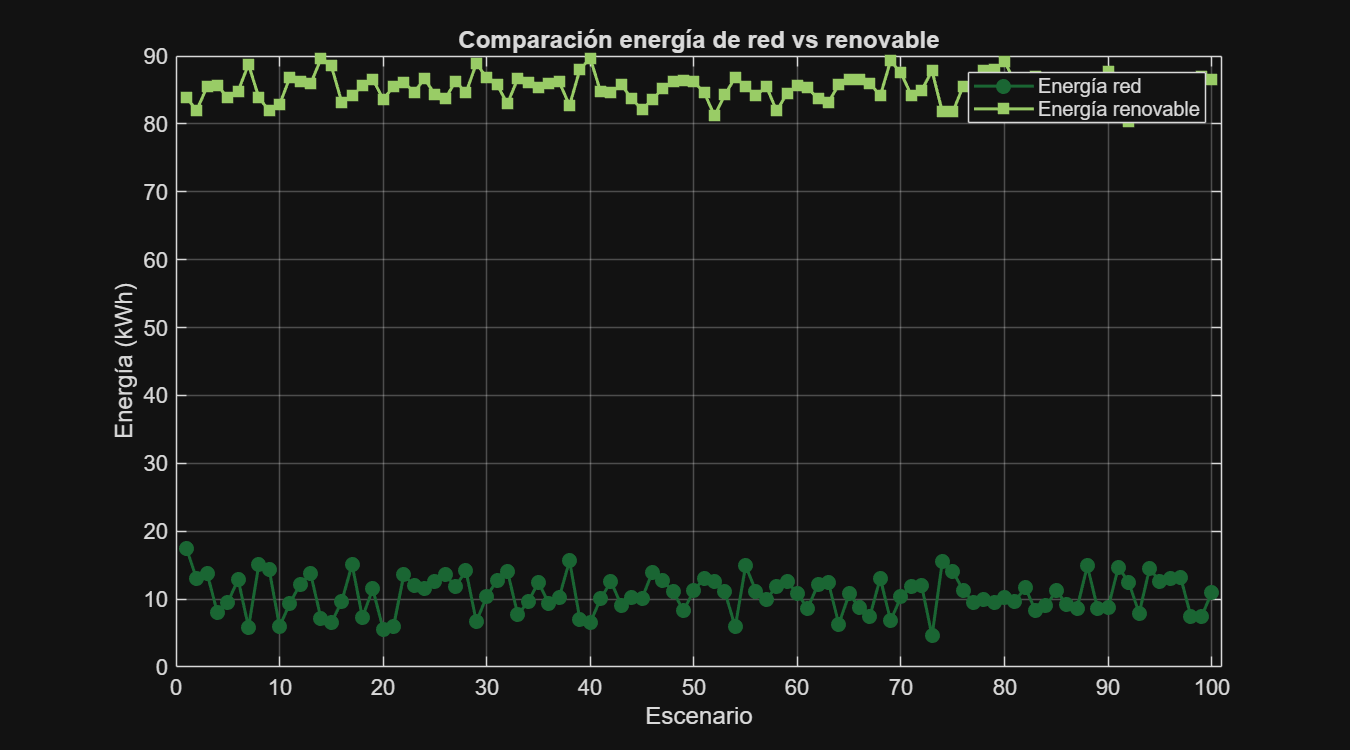

escenarios = 1:num_escenarios;
%% ── Gráfica 1: Energía red vs renovable ──────────────────────
figure('Name','Energía absoluta','Position',[100 650 900 500]);

plot(escenarios, Energia_red_total, '-o', ...
    'Color',[0.1 0.4 0.2], 'LineWidth',1.5, ...
    'MarkerFaceColor',[0.1 0.4 0.2]);
hold on;

plot(escenarios, Energia_renovable_total, '-s', ...
    'Color',[0.6 0.8 0.4], 'LineWidth',1.5, ...
    'MarkerFaceColor',[0.6 0.8 0.4]);

legend('Energía red','Energía renovable','Location','northeast');

xlabel('Escenario');
ylabel('Energía (kWh)');
title('Comparación energía de red vs renovable');

xlim([0, num_escenarios+1]);
grid on;
box on;
set(gca,'FontSize',11);

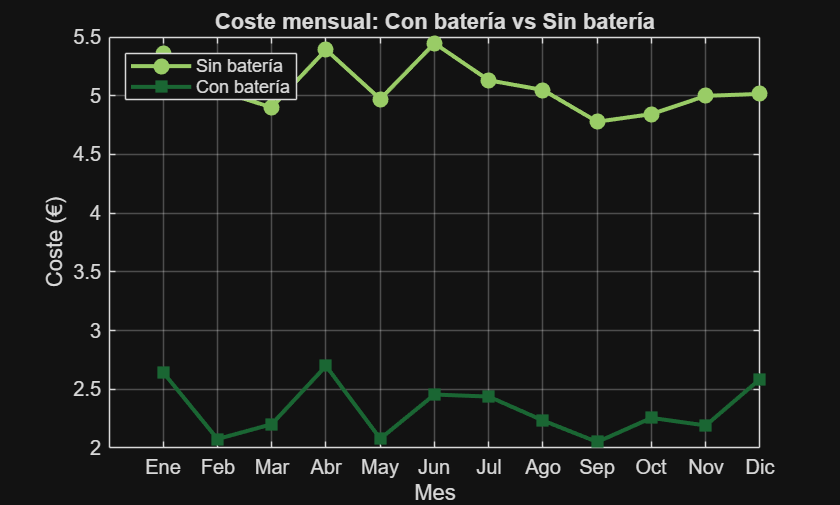

%% ── Promedio mensual ────────────────────────────────────────────────
meses = 1:12;

Coste_mensual_con     = zeros(1,12);
Coste_mensual_sin     = zeros(1,12);

escenarios_por_mes = floor(num_escenarios / 12);

for m = 1:12
    idx_inicio = (m-1)*escenarios_por_mes + 1;
    idx_fin    = m*escenarios_por_mes;

    Coste_mensual_con(m) = mean(Costes(idx_inicio:idx_fin));
    Coste_mensual_sin(m) = mean(Costes_sin_batt(idx_inicio:idx_fin));
end

%% ── Gráfica 2: Coste mensual con vs sin batería ─────────────────────────────────
figure;

% Verde claro (sin batería)
plot(meses, Coste_mensual_sin, '-o', ...
    'Color', [0.6 0.8 0.4], 'LineWidth', 2, ...
    'MarkerFaceColor', [0.6 0.8 0.4]); 
hold on;

% Verde oscuro (con batería)
plot(meses, Coste_mensual_con, '-s', ...
    'Color', [0.1 0.4 0.2], 'LineWidth', 2, ...
    'MarkerFaceColor', [0.1 0.4 0.2]);

grid on;
xlabel('Mes');
ylabel('Coste (€)');
title('Coste mensual: Con batería vs Sin batería');

xticks(1:12);
xticklabels({'Ene','Feb','Mar','Abr','May','Jun','Jul','Ago','Sep','Oct','Nov','Dic'});

legend('Sin batería','Con batería','Location','northwest');

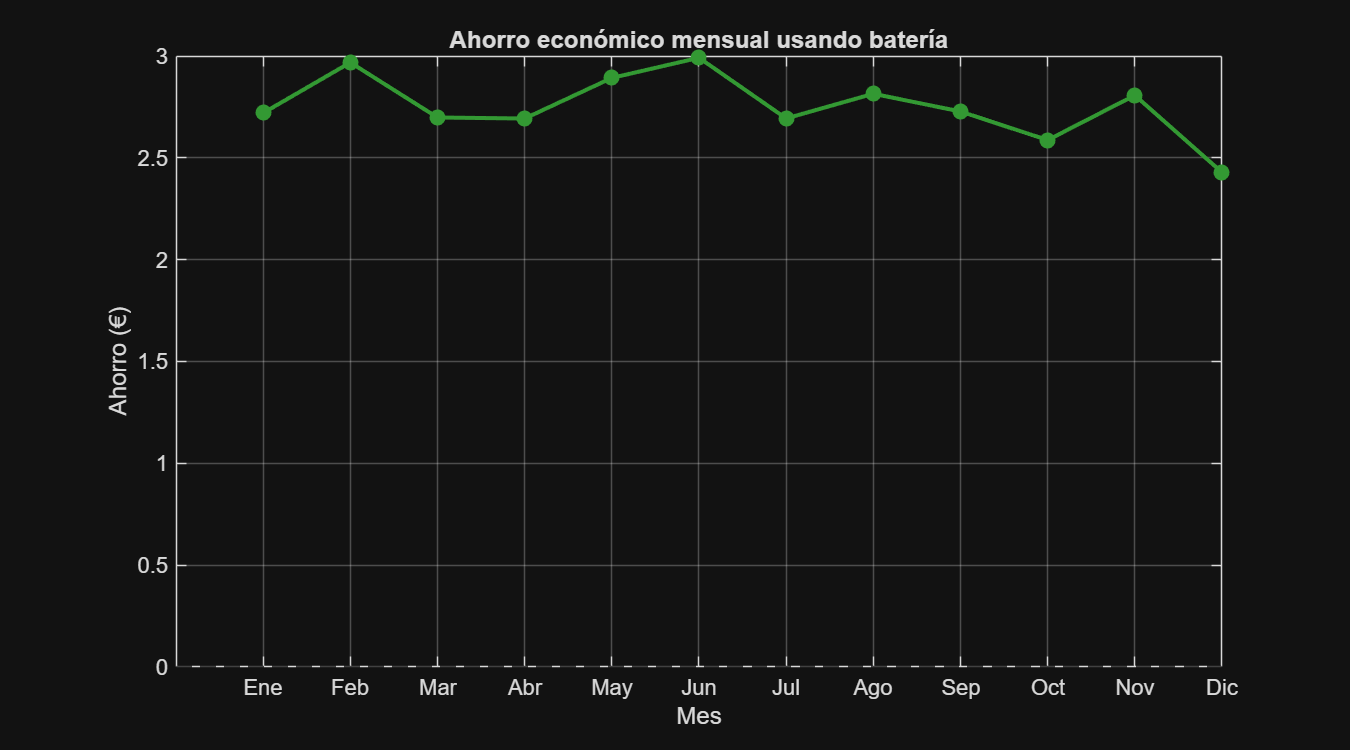

%% ── Gráfica 3: Ahorro mensual ────────────────────────────────────────────
Ahorro_mensual = Coste_mensual_sin - Coste_mensual_con;

figure('Name','Ahorro mensual','Position',[100 100 900 500]);

plot(meses, Ahorro_mensual, '-o', ...
    'Color',[0.2 0.6 0.2], 'LineWidth',2, ...
    'MarkerFaceColor',[0.2 0.6 0.2]);

hold on;
yline(0, '--k');

xlabel('Mes');
ylabel('Ahorro (€)');
title('Ahorro económico mensual usando batería');

xticks(1:12);
xticklabels({'Ene','Feb','Mar','Abr','May','Jun','Jul','Ago','Sep','Oct','Nov','Dic'});

grid on;
box on;
set(gca,'FontSize',11);

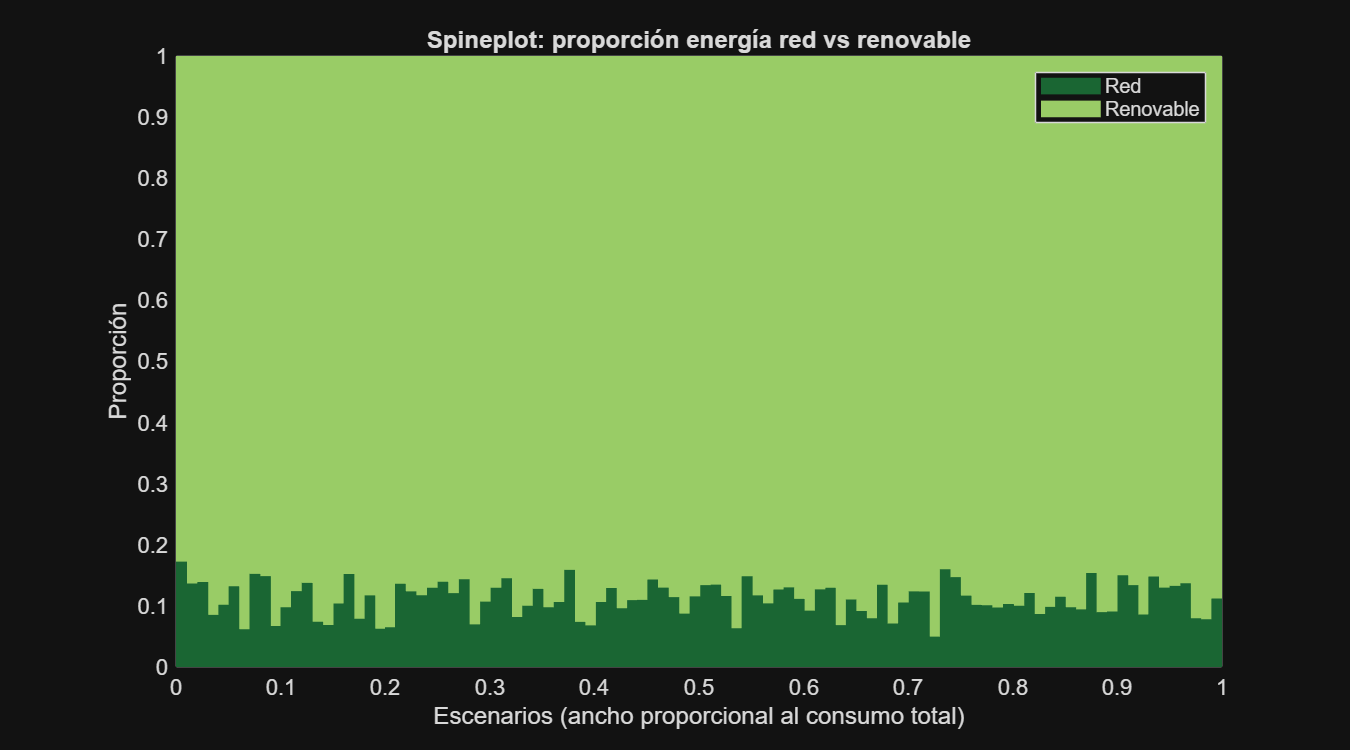

%% ── Gráfica 4: Porcentaje de uso de energía con vs sin batería ───────────────────────────────────────────
figure('Name','Spineplot energético','Position',[600 200 900 500]);
hold on;

total = Energia_red_total + Energia_renovable_total;

% Normalizar anchos (para que ocupen todo el eje X)
widths = total / sum(total);

x_start = 0;

for i = 1:length(escenarios)
    
    w = widths(i);
    
    % proporciones
    p_red = Energia_red_total(i) / total(i);
    p_ren = Energia_renovable_total(i) / total(i);
    
    % Coordenadas del rectángulo (RED)
    x_rect = [x_start, x_start+w, x_start+w, x_start];
    y_red  = [0, 0, p_red, p_red];
    
    fill(x_rect, y_red, [0.1 0.4 0.2], 'EdgeColor','none');
    
    % Coordenadas del rectángulo (RENOVABLE)
    y_ren = [p_red, p_red, 1, 1];
    
    fill(x_rect, y_ren, [0.6 0.8 0.4], 'EdgeColor','none');
    
    x_start = x_start + w;
end

% Estética
xlim([0 1]);
ylim([0 1]);

xlabel('Escenarios (ancho proporcional al consumo total)');
ylabel('Proporción');

title('Spineplot: proporción energía red vs renovable');

legend({'Red','Renovable'}, 'Location','northeast');

box on;
grid on;
set(gca,'FontSize',11);